# PROGETTO ZERO INTERLEAVING

% Lo script deve ricostruire una sequenza x_n a partire da una sua versione "zero interleaved" indicata con y_n
% in cui ogni M campioni sono inseriti M-1 zeri (al posto dei campioni originari)

% Esempio:
% sequenza originaria                       x_n = 1,2,3,4,5,6,7,8,9,10...
% sequenza zero_interleaved (fattore M = 3)  y_n= 1,0,0,4,0,0,7,0,0,10...

% La sequenza di partenza x_n ha 400 campioni ed è¨ fornita nel file zerointerleaving.mat

% Si richiede che lo script Matlab esegua le seguenti operazioni:

% - generi la sequeza zero-interleaved y_n con M variabile (M = 2,3,...),
% cioè si deve poter scegliere il numero di campioni (M-1) da azzerare.

% - permetta di scegliere la posizione dei campioni non nulli, es. si chiede la
% possibilitÃ di generare M possibili sequenze con campioni non nulli in posizione
% Mk, Mk+1, Mk+2, ... Mk+(M-1) con k = 0,1,2,...

% - rappresenti graficamente la sequenza x_n e le sequenze y_n (zero_interleaved)
% nel dominio del tempo e delle frequenze (trasformata discreta di Fourier).
%
% - rappresenti graficamente nel dominio del tempo e delle frequenze il filtro impiegato per la ricostruzione
% della sequenza x_n

% - rappresenti graficamente la sequenza originaria x_n e la sua versione
% ricostruita, mostrando che la sequenza ricostruita è la stessa qualunque
% sia la scelta della posizione dei campioni non nulli (purché non vi siano fenomeni di alias).

% - permetta di valutare il massimo valore di M che non produce distorsione del segnale ricostrutito.

% Strutturare lo script Matlab in modo tale che possa essere rapidamente adattato per gestire sequenze in ingresso
% diverse da quella assegnata (es. diverso numero di campioni).
% Definire in modo chiaro le variabili utilizzate e commentare sinteticamente i vari passi dello script.

## **START**

close all
clear
clc
%prompt = ('Inserisci nome file :  ');
%nome_file = input (prompt, 's');
%load (nome_file);
load zerointerleaving.mat
dim = length(x);
M = input('Inserisci M: ');
f_s = 1/M; %frequenza di campionamento, ma potremmo toglierla perché non serve
a_x = 'Campioni';

## **ZERO-INTERLEAVING**

y_n = zeros(M,dim); %crea una matrice di zeri contenente le M sequenze lungo le righe
Yf_n = y_n; %copia la matrice creata in quella che sarà la trasformata
for j = 1:M %ciclo per creare M sequenze zero-interleaved
    i = j;
    while i<dim+1
        y_n(j,i) = x(i);
        i = i+M;
    end
end

## **TRASFORMAZIONI** 

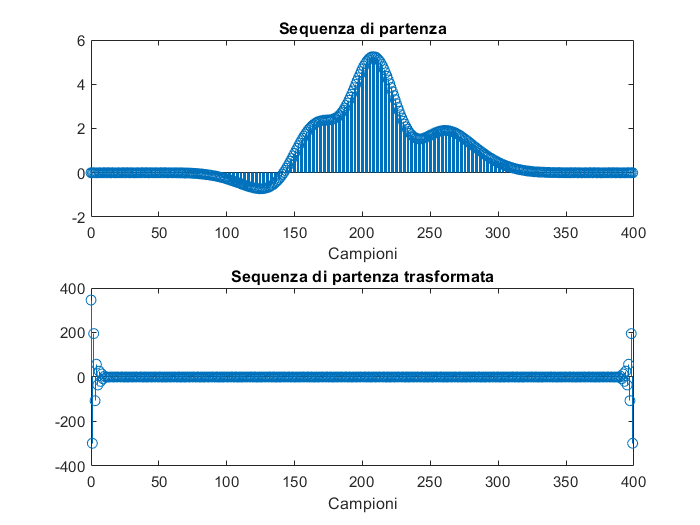

n = (0:dim-1);
Xf=fft(x);
figure
subplot(2,1,1)
stem (n,x);
xlabel (a_x)
title('Sequenza di partenza')
%pause
subplot(2,1,2)
stem (n,real(Xf));
xlabel (a_x)
title('Sequenza di partenza trasformata')

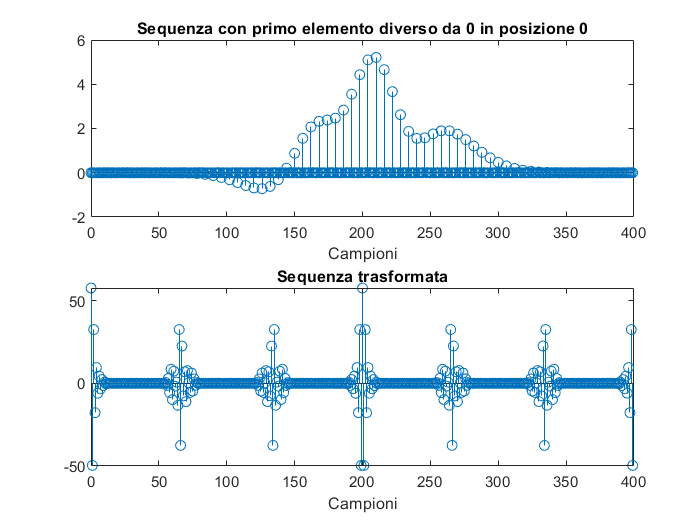

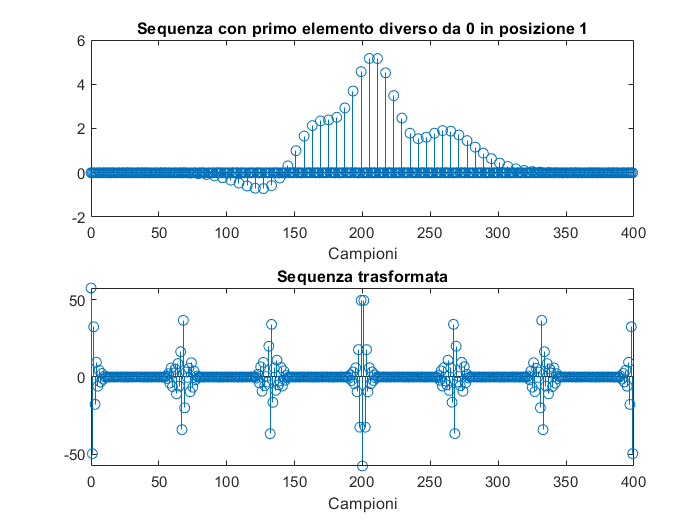

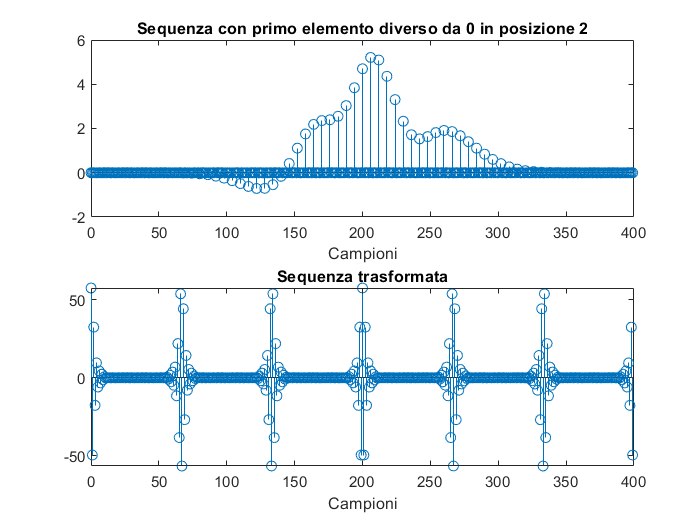

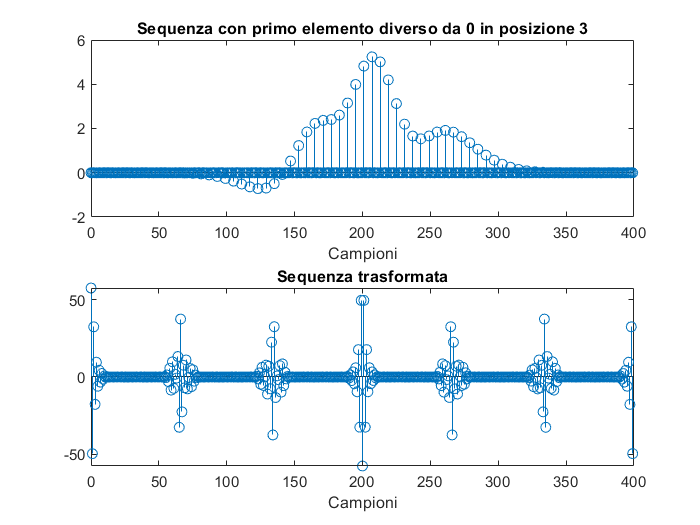

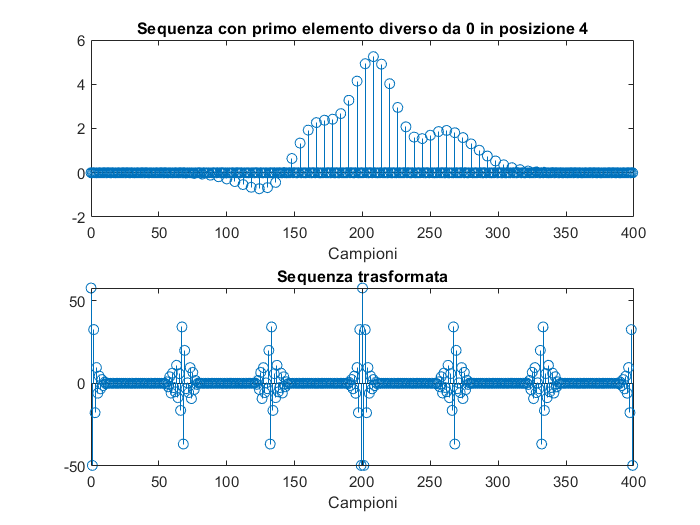

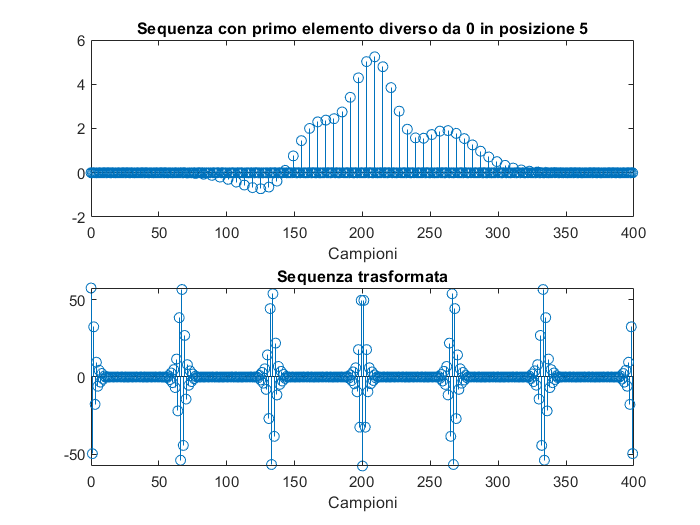

%pause
for k = 1:M
    titolo = 'Sequenza con primo elemento diverso da 0 in posizione %d';
    pos = k-1; %indice di posizione che viene riportato nel grafico
    Yf_n(k,:) = fft(y_n(k,:));
    figure
    subplot(2,1,1)
    stem(n,y_n(k,:));
    xlabel (a_x)
    title(sprintf(titolo,pos))
    subplot(2,1,2)
    stem(n,real(Yf_n(k,:)));
    xlabel (a_x)
    title('Sequenza trasformata')
    %pause
end

## **FILTRO**

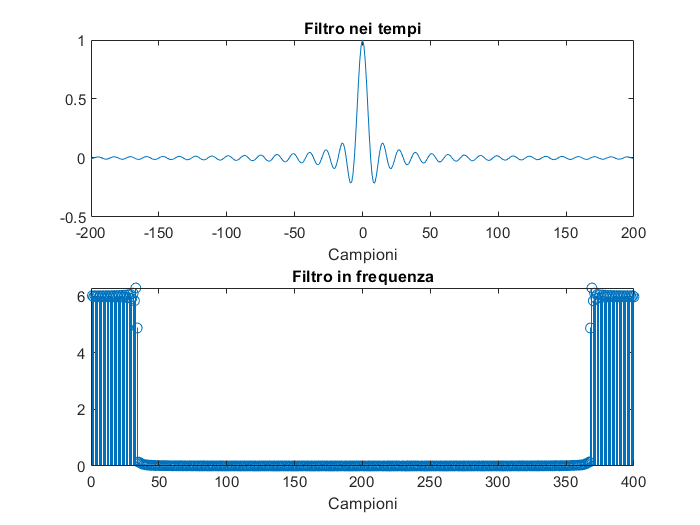

figure
t=-dim/2:dim/2-1;
filtro_t=sinc(t/M);
filtro=abs(fft(filtro_t));
subplot (2,1,1)
plot(t,filtro_t);
title('Filtro nei tempi')
xlabel (a_x)
subplot (2,1,2)
stem(filtro);
title('Filtro in frequenza')
xlabel (a_x)

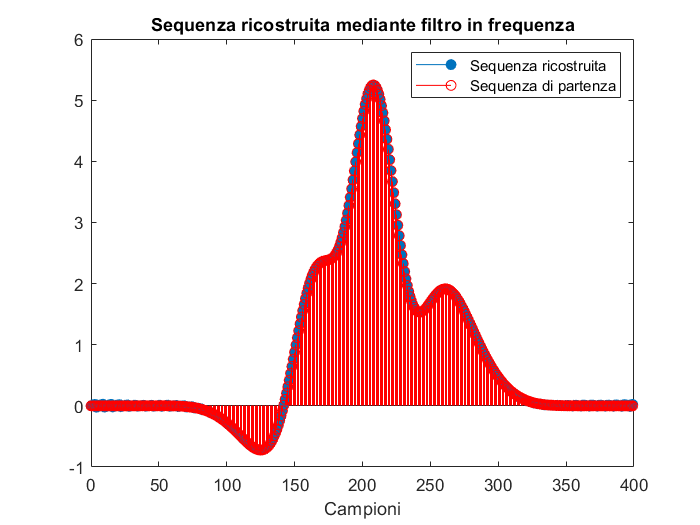

Errore quadratico medio sequenza 1 = 3.393613e-05 


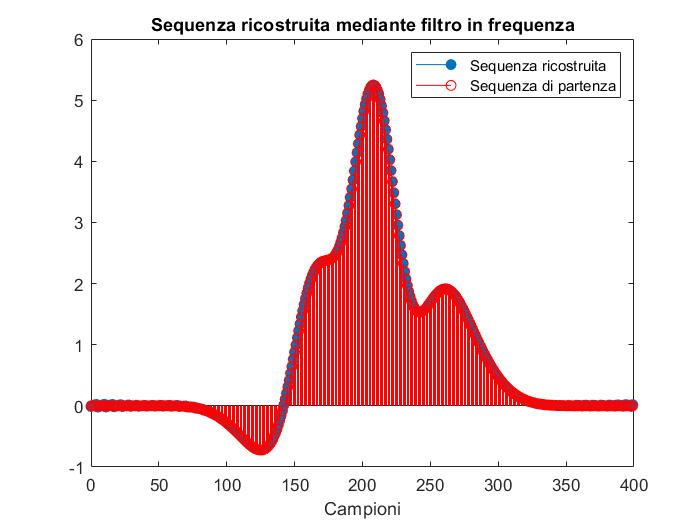

Errore quadratico medio sequenza 2 = 3.288946e-05 


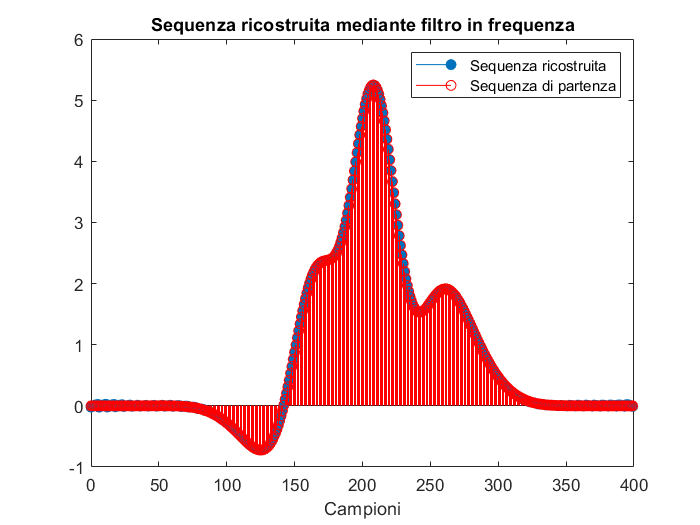

Errore quadratico medio sequenza 3 = 3.283603e-05 


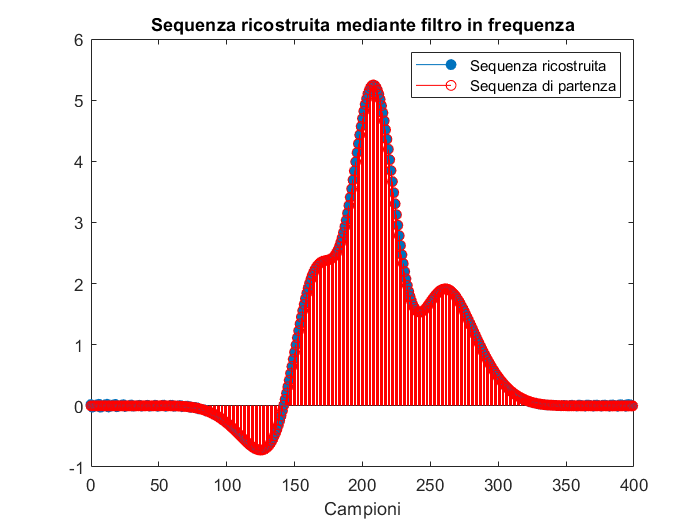

Errore quadratico medio sequenza 4 = 3.371608e-05 


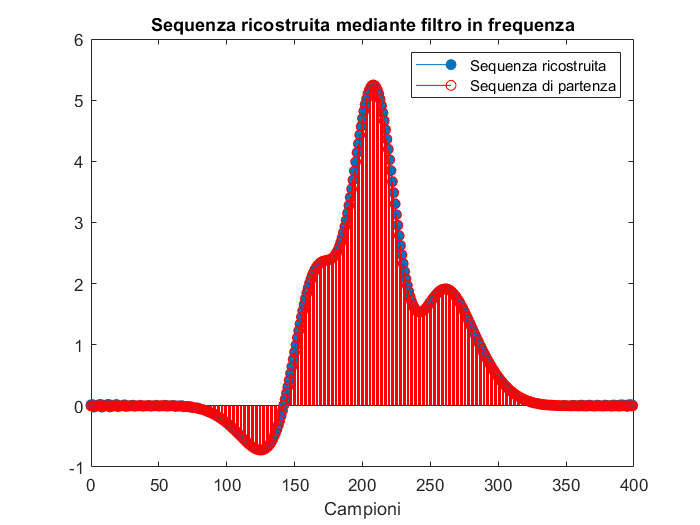

Errore quadratico medio sequenza 5 = 3.472544e-05 


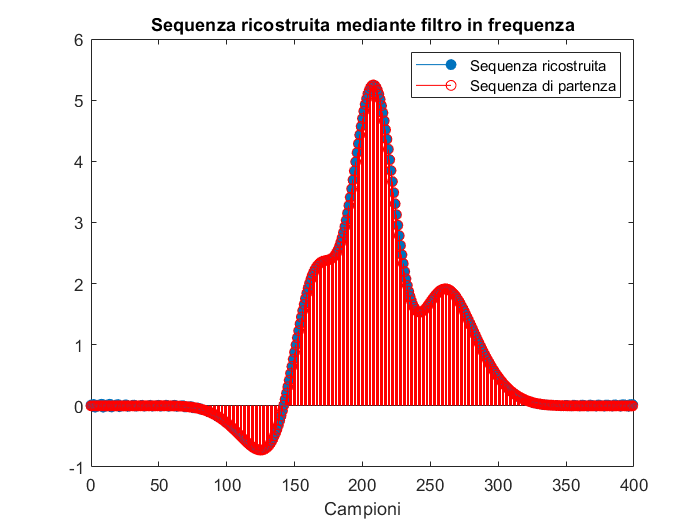

Errore quadratico medio sequenza 6 = 3.482912e-05 


%pause
Zf_n=zeros(M,dim);
z=zeros(M,(2*dim)-1);
u=zeros(M,dim);
%errorequadraticotempo=zeros(M,dim);
for i=1:M
    figure
    %figure(3)
    Zf_n(i,:) = Yf_n(i,:).*filtro;
    z(i,:) = conv(y_n(i,:),filtro_t);
    u(i,:) = z(i,(dim/2)+1:(3/2)*dim); %range di campioni utili della sequenza ricostruita
    errorequadratico=immse(x(1,:),u(i,:));
    %subplot(2,1,1)
    stem(n,u(i,:),'filled','DisplayName','Sequenza ricostruita');
    xlabel (a_x)
    title('Sequenza di partenza e ricostruita')
    legend
    %title('Sequenza ricostruita mediante filtro nei tempi')
    %subplot(2,1,2)
    hold on
    stem (n,x,'r','DisplayName','Sequenza di partenza');
    %xlabel ('Campioni')
    %title('Sequenza di Partenza')
    %stem(abs(errorequadraticotempo(i,:)));
    hold off
    %subplot(3,1,3);
    %stem(real(Zf_n(i,:)));
    title('Sequenza ricostruita mediante filtro in frequenza')
    %pause
    format shortE;
    output = 'Errore quadratico medio sequenza %d = %d \n';
    fprintf(output,i,errorequadratico)
    if errorequadratico > 1.0e-03
        output = 'Errore quadratico medio superiore al limite! \n\n';
        fprintf(output)
    end
    %subplot(4,1,4)
    %stem(errorequadraticofrequenza(i,:));
    %pause
end

## **ADD ?**

%   - error('M scelto non rispetta il teorema del campionamento!');
%   - per M più grande di un certo valore si va in alias, la sequenza si deforma
%     il filtro deve eliminare le repliche spettrali: M = numero di repliche
%   - relazionare sul grafico M con lo scarto quadratico

%NOTA:  I COMMENTI RIMASTI CONTENGONO QUASI ESCLUSIVAMENTE 
%       CODICE DA RIAGGIUNGERE A SCRIPT COMPLETATO